$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{K\,{X_{3}}^{2}}{M\,{X_{1}}^{2}} & 0 & -\frac{2\,K\,X_{3}}{M\,X_{1}}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$H = \frac{2\,K\,X_{1}\,X_{3}}{\left(R+L\,s\right)\,\left(K\,{X_{3}}^{2}-M\,{X_{1}}^{2}\,s^{2}\right)}$$

$$x1 = \frac{K\,V^{2}}{G\,M\,R^{2}}$$

x2 = 0

$$x3 = \frac{V}{R}$$

l1 = 0.5850

l2 = 0.7150

R1 = 24.9300

R2 = 30.4700

v1 = 93.5000

v2 = 126.5000

$$Aex = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{11316115319027\,R^{2}}{1800000000\,V^{2}} & 0 & -\frac{97639\,R}{5000\,V}\\ 0 & 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$Bex = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

$$q1 = \frac{11316115319027\,R^{2}}{1800000000\,V^{2}}$$

$$q2 = -\frac{97639\,R}{5000\,V}$$

$$q3 = -\frac{R}{L}$$

$$q4 = \frac{1}{L}$$

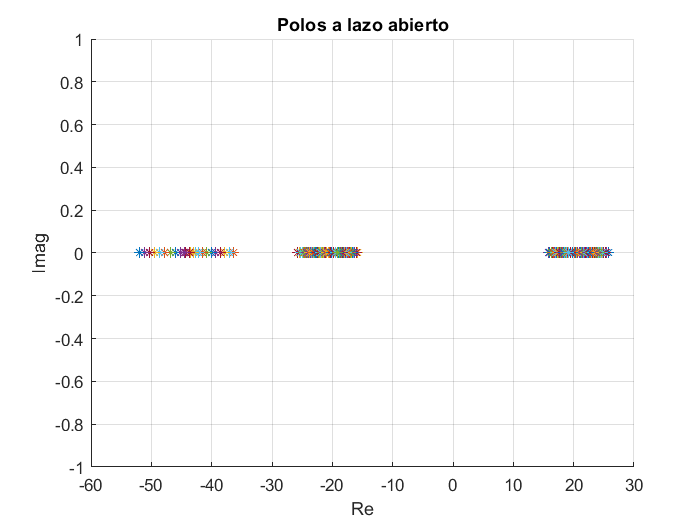


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.136315
     2                        0.016857
     3                        0.010524
     4                    5.436042e-03
     5                    2.817305e-03
     6                    2.817305e-03
     7                    2.203993e-04
     8                    2.203993e-04
     9                    2.001192e-05
    10                    2.001192e-05
    11                    2.527400e-06
    12                    2.527400e-06
    13                    3.212143e-07
    14                    3.212143e-07
    15                    4.118060e-08
    16                    4.118060e-08
    17                    5.873883e-09
    18                    5.873883e-09
    19                    8.711692e-10
    20                    8.711692e-10
    21

K = 	1.0e+32 *

   -0.0000    2.2128   -0.0189   -0.0220


Unrecognized function or variable 'printf'.

% definimos la variable compleja s
syms s K M R G L V X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad

% Creacion de las matrices
In =  [1 0 0;0 1 0;0 0 1];
A = [0 1 0; (K*X3^2)/(M*X1^2) 0 (-2*K*X3)/(M*X1);0 0 -R/L]
B = [0;0;1/L]
C = [1 0 0]

% Funcion de transferencia 
H = C*inv(s*In - A)*B

%Puntos de equilibrio
x1 = (K*V^2)/(M*G*R^2)
x2 = 0
x3 = V/R


%Seleccion de Variables contantes
g = 9.7639;
r = 27.7;
l = 0.65;
k = 1.8*10^-4;
m = 11.87*10^-3;
v=110;

%Seleccion de variables inciertas
%La inductancia varia en un 10%
l1=l*0.9
l2=l*1.1
%Se asume una resistencia con una tolerancia del 10%
R1=r*0.9
R2=r*1.1
%Se tension varia en un 15%
v1=v*0.85
v2=v*1.15

%Sustitucion de valores
Aq = subs(A, [X1 X3], [x1 x3]);
Aq= subs(Aq, [K M G],[k m g]);
Aex = [0 -C; [0; 0; 0] Aq]
Bex=[0; B]

%Terminos variables de la matriz A
q1=Aex(3,2)
q2=Aex(3,4)
q3=Aex(4,4)
q4=Bex(4,1)

%Polos a lazo abierto
figure
for  rq=R1:0.5:R2
    for vq = v1:2:v2
        for lq = l1:0.1:l2
            q1q = subs(q1, [V R], [vq rq]);
            q2q = subs(q2, [V R], [vq rq]);
            q3q = subs(q3, [R L], [rq lq]);
            Aqqq=[0 1 0; q1q 0 q2q; 0 0 q3q];
            p=eig(Aqqq);
            hold on
            plot(real(p(1)),imag(p(1)),'*')
            plot(real(p(2)),imag(p(2)),'*')
            plot(real(p(3)), imag(p(3)), '*')
        end
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off

%Politopo

% BoxPlot3(5.850,8.93,5.5,1.3,5.54,11.0)
% xlabel("L [H*10]");ylabel("R [ohm]");zlabel("V [v*10^-1]");

%Planta
A1 = subs(Aex, [V R L], [v1 R1 l1]); %Vmin, Rmin, Lmin
A2 = subs(Aex, [V R L], [v2 R1 l1]); %Vmin, Rmin, Lmax
A3 = subs(Aex, [V R L], [v1 R2 l1]); %Vmin, Rmax, Lmin
A4 = subs(Aex, [V R L], [v2 R2 l1]); %Vmin, Rmax, Lmax
A5 = subs(Aex, [V R L], [v1 R1 l2]); %Vmax, Rmin, Lmin
A6 = subs(Aex, [V R L], [v2 R1 l2]); %Vmax, Rmin, Lmax
A7 = subs(Aex, [V R L], [v1 R2 l2]); %Vmax, Rmax, Lmin
A8 = subs(Aex, [V R L], [v2 R2 l2]); %Vmax, Rmax, Lmax

B1 = subs(Bex, L, l1); %Lmin
B2 = subs(Bex, L, l2); %Lmax


% Especificaciones región reubicación de polos

Alfa=0;

Ro=33;

Theta = 0.1;
% Creación sistema LMI
setlmis([])

% Variables LMIs
S=lmivar(1,[4 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 4]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% % 𝑨1S + 𝑺𝑨1𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([2 1 1 S],A1,1,'s');
% lmiterm([2 1 1 R],B1,1,'s');
% lmiterm([2 1 1 S],2*Alfa,1);
% 
% % 𝑨2S+ 𝑺𝑨2𝑻 + 𝑩1R + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([3 1 1 S],A2,1,'s');
% lmiterm([3 1 1 R],B1,1,'s');
% lmiterm([3 1 1 S],2*Alfa,1);
% 
% % 𝑨3S + 𝑺𝑨3𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([4 1 1 S],A3,1,'s');
% lmiterm([4 1 1 R],B1,1,'s');
% lmiterm([4 1 1 S],2*Alfa,1);
% 
% % 𝑨4S+ 𝑺𝑨4𝑻 + 𝑩1R + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([5 1 1 S],A4,1,'s');
% lmiterm([5 1 1 R],B1,1,'s');
% lmiterm([5 1 1 S],2*Alfa,1);
% 
% % 𝑨1S + 𝑺𝑨1𝑻 + 𝑩2S + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([6 1 1 S],A5,1,'s');
% lmiterm([6 1 1 R],B2,1,'s');
% lmiterm([6 1 1 S],2*Alfa,1);
% 
% % 𝑨2S+ 𝑺𝑨2𝑻 + 𝑩2R + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([7 1 1 S],A6,1,'s');
% lmiterm([7 1 1 R],B2,1,'s');
% lmiterm([7 1 1 S],2*Alfa,1);
% 
% % 𝑨3S + 𝑺𝑨3𝑻 + 𝑩2S + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([8 1 1 S],A7,1,'s');
% lmiterm([8 1 1 R],B2,1,'s');
% lmiterm([8 1 1 S],2*Alfa,1);
% 
% % 𝑨4S+ 𝑺𝑨4𝑻 + 𝑩2R + 𝑹𝑩3 + 𝟐𝜶𝑺 < 𝟎
% lmiterm([9 1 1 S],A8,1,'s');
% lmiterm([9 1 1 R],B2,1,'s');
% lmiterm([9 1 1 S],2*Alfa,1);
% 
% % Restricciones asociadas al parámetro Ro
% 
% % (A1,B1)
% lmiterm([10 1 1 S],-Ro,1);
% lmiterm([10 1 2 S],A1,1);
% lmiterm([10 1 2 R],B1,1);
% lmiterm([10 2 2 S],-Ro,1);
% 
% % (A2,B1)
% lmiterm([11 1 1 S],-Ro,1);
% lmiterm([11 1 2 S],A2,1);
% lmiterm([11 1 2 R],B1,1);
% lmiterm([11 2 2 S],-Ro,1);
% 
% % (A3,B1)
% lmiterm([12 1 1 S],-Ro,1);
% lmiterm([12 1 2 S],A3,1);
% lmiterm([12 1 2 R],B1,1);
% lmiterm([12 2 2 S],-Ro,1);
% 
% % (A4,B1)
% lmiterm([13 1 1 S],-Ro,1);
% lmiterm([13 1 2 S],A4,1);
% lmiterm([13 1 2 R],B1,1);
% lmiterm([13 2 2 S],-Ro,1);
% 
% % (A1,B2)
% lmiterm([14 1 1 S],-Ro,1);
% lmiterm([14 1 2 S],A5,1);
% lmiterm([14 1 2 R],B2,1);
% lmiterm([14 2 2 S],-Ro,1);
% 
% % (A2,B2)
% lmiterm([15 1 1 S],-Ro,1);
% lmiterm([15 1 2 S],A6,1);
% lmiterm([15 1 2 R],B2,1);
% lmiterm([15 2 2 S],-Ro,1);
% 
% % (A3,B2)
% lmiterm([16 1 1 S],-Ro,1);
% lmiterm([16 1 2 S],A7,1);
% lmiterm([16 1 2 R],B2,1);
% lmiterm([16 2 2 S],-Ro,1);
% 
% % (A4,B2)
% lmiterm([17 1 1 S],-Ro,1);
% lmiterm([17 1 2 S],A8,1);
% lmiterm([17 1 2 R],B2,1);
% lmiterm([17 2 2 S],-Ro,1);


% Restricciones de theta 

% (A1, B1)

lmiterm([2 1 1 S], sin(Theta)*A1, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([2 1 1 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([2 1 2 S], cos(Theta)*A1, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([2 1 2 S],1, -cos(Theta)*A1')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([2 1 2 R], cos(Theta)*B1, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([2 1 2 -R], 1, -cos(Theta)*B1')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([2 2 2 S], sin(Theta)*A1, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([2 2 2 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'

% (A2, B1)

lmiterm([3 1 1 S], sin(Theta)*A2, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([3 1 1 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([3 1 2 S], cos(Theta)*A2, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([3 1 2 S],1, -cos(Theta)*A2')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([3 1 2 R], cos(Theta)*B1, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([3 1 2 -R], 1, -cos(Theta)*B1')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([3 2 2 S], sin(Theta)*A2, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([3 2 2 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'

% (A3, B1)

lmiterm([4 1 1 S], sin(Theta)*A3, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([4 1 1 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([4 1 2 S], cos(Theta)*A3, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([4 1 2 S],1, -cos(Theta)*A3')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([4 1 2 R], cos(Theta)*B1, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([4 1 2 -R], 1, -cos(Theta)*B1')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([4 2 2 S], sin(Theta)*A3, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([4 2 2 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'

% (A4, B1)

lmiterm([5 1 1 S], sin(Theta)*A4, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([5 1 1 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([5 1 2 S], cos(Theta)*A4, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([5 1 2 S],1, -cos(Theta)*A4')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([5 1 2 R], cos(Theta)*B1, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([5 1 2 -R], 1, -cos(Theta)*B1')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([5 2 2 S], sin(Theta)*A4, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([5 2 2 R], sin(Theta)*B1, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'

% (A5, B2)

lmiterm([6 1 1 S], sin(Theta)*A5, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([6 1 1 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([6 1 2 S], cos(Theta)*A5, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([6 1 2 S],1, -cos(Theta)*A5')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([6 1 2 R], cos(Theta)*B2, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([6 1 2 -R], 1, -cos(Theta)*B2')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([6 2 2 S], sin(Theta)*A5, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([6 2 2 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'

% (A6, B2)

lmiterm([7 1 1 S], sin(Theta)*A6, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([7 1 1 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([7 1 2 S], cos(Theta)*A6, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([7 1 2 S],1, -cos(Theta)*A6')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([7 1 2 R], cos(Theta)*B2, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([7 1 2 -R], 1, -cos(Theta)*B2')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([7 2 2 S], sin(Theta)*A6, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([7 2 2 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'


% (A7, B2)

lmiterm([8 1 1 S], sin(Theta)*A7, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([8 1 1 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([8 1 4 S], cos(Theta)*A7, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([8 1 2 S],1, -cos(Theta)*A7')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([8 1 2 R], cos(Theta)*B2, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([8 1 2 -R], 1, -cos(Theta)*B2')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([8 2 2 S], sin(Theta)*A7, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([8 2 2 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'


% (A8, B2)

lmiterm([9 1 1 S], sin(Theta)*A8, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([9 1 1 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*B1*R + sin(Theta)*R'*B1'
lmiterm([9 1 2 S], cos(Theta)*A8, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([9 1 2 S],1, -cos(Theta)*A8')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([9 1 2 R], cos(Theta)*B2, 1)
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([9 1 2 -R], 1, -cos(Theta)*B2')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([9 2 2 S], sin(Theta)*A8, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'
lmiterm([9 2 2 R], sin(Theta)*B2, 1, 's')
%sin(Theta)*A1*S + sin(Theta)*S*A1'

% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS);

% Solución
S=dec2mat(LMISYS,xfeas,S);
R=dec2mat(LMISYS,xfeas,R);

K=R*inv(S)
        
if(tmin < 0)
    syms R
    figure
    for  rq=R1:0.5:R2
        for vq = v1:2:v2
            for lq = l1:0.1:l2
                q1q = subs(q1, [V R], [vq rq]);
                q2q = subs(q2, [V R], [vq rq]);
                q3q = subs(q3, [R L], [rq lq]);
                Aqqq=[0 -1 0 0;0 0 1 0;0 q1q 0 q2q;0 0 0 q3q];
                Bqqq=[0; 0; 0; 1/lq];
                p=eig(Aqqq + Bqqq*K);
                hold on
                plot(real(p(1)),imag(p(1)),'*')
                plot(real(p(2)),imag(p(2)),'*')
                plot(real(p(3)), imag(p(3)), '*')
            end
        end
    end
    grid
    xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
    hold off
    
else 
    printf('esa k no sirve pa media verga')
end 